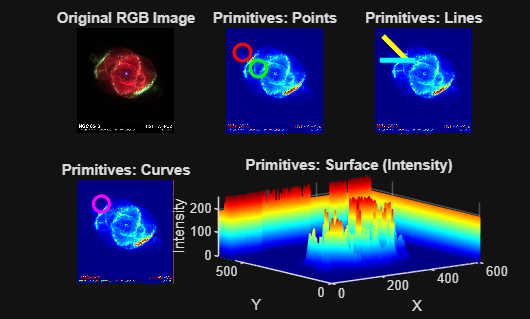

% ---- IMAGE GEOMETRY PRIMITIVES DEMO ----

% 1. Read an in-built RGB image
%img = imread('peppers.png');   % You can replace with other in-built images
img = imread('ngc6543a.jpg');
gray_img = rgb2gray(img);      % Convert to grayscale for geometry illustration

figure;

% Display original image
subplot(2,3,1);
imshow(img); title('Original RGB Image');

% 2. Points (mark specific pixels)
subplot(2,3,2);
imshow(gray_img); hold on;
plot(100, 150, 'ro', 'MarkerSize', 10, 'LineWidth', 2); % red point
plot(200, 250, 'go', 'MarkerSize', 10, 'LineWidth', 2); % green point
title('Primitives: Points');

% 3. Lines
subplot(2,3,3);
imshow(gray_img); hold on;
line([50 200], [50 200], 'Color', 'y', 'LineWidth', 3); % diagonal line
line([30 250], [200 200], 'Color', 'c', 'LineWidth', 3); % horizontal line
title('Primitives: Lines');

% 4. Curves
subplot(2,3,4);
imshow(gray_img); hold on;
theta = linspace(0, 2*pi, 100);
x = 150 + 50*cos(theta); 
y = 150 + 50*sin(theta); 
plot(x, y, 'm-', 'LineWidth', 2); % circle curve
title('Primitives: Curves');

% 5. Surfaces (3D intensity surface of grayscale image)
subplot(2,3,[5 6]);
mesh(double(gray_img)); 
colormap jet; shading interp;
title('Primitives: Surface (Intensity)');
xlabel('X'); ylabel('Y'); zlabel('Intensity');

% Save the figure
saveas(gcf, 'Geometry_Primitives.png');

disp('✓ Figure saved as Geometry_Primitives.png');

✓ Figure saved as Geometry_Primitives.png
